# Exposure duration and flare

Show the impact of flare as we change the exposure duration.  We create a simple test scene comprising a background image with a bright spot, like a superimposed light source.  The scene has a dynamic range of 4 log units.  We then capture and display the scene at different exposure durations.  At the short exposure durations we see no flare.  As the exposure duration increases, the flare becomes evident, superimposed on the background image.

Created as part of our study of hdr sensor calculations.

## Initialize ISET

ieInit

## Make the scene.  FruitMCC with a single bright spot (like a light source).

We specify the scene have a dynamic range of 10^4.  (I am concerned that sometimes we use log(DR) and sometimes DR).

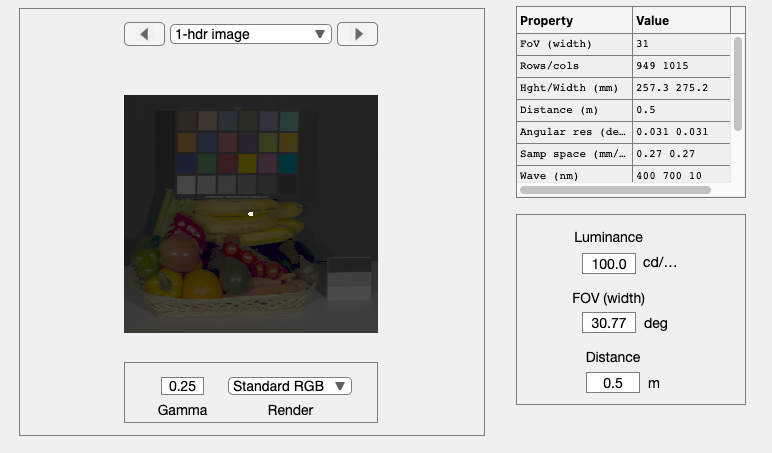

scene = sceneCreate('hdr image',...
    'npatches',1,...
    'dynamic range',4,...
    'background','FruitMCC_6500.tif',...
    'patch shape','circle', ...
    'patch size',10);

% We will show this later.
sceneRGB = sceneGet(scene,'srgb');
sceneWindow(scene,'gamma',0.25,'render flag','rgb','show',true);

drawnow;

## Plot a line through the bright spot to confirm the dynamic range

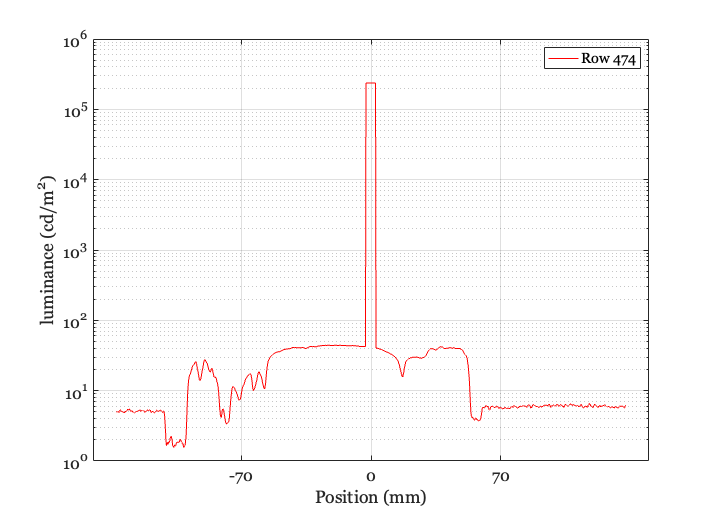

scenePlot(scene,'luminance hline',[1 474]);
set(gca,'yscale','log');

drawnow;

## Render through simple optics

We can set the aperture properties for the flare.

[oi,wvf] = oiCreate('wvf');

% High sampling resolution.  Not really needed.
wvf = wvfSet(wvf,'spatial samples',1024);

% Default wvf parameters, make 3-sided (triangular) aperture.
params = wvfApertureP;
params.nsides = 3;
aperture = wvfAperture(wvf,params);

oi = oiSet(oi,'optics fnumber',1.7);
oi = oiSet(oi,'optics focal length',4.38e-3,'m');
oi = oiCompute(oi, scene,'crop',true,'pixel size',1.5e-6,'aperture',aperture);

## Create sensor image

% sensor = sensorCreate('imx363');
sensor = sensorCreate('ar0132at',[],'rgb');
sensor = sensorSet(sensor,'match oi',oi);
sensor = sensorSet(sensor,'pixel voltage swing',1);

eTime  = autoExposure(oi,sensor,0.95,'luminance');

% [HH,mm] = hms(datetime('now'));

% Exposure durations 
expDuration = logspace(log10(eTime)+1.5,log10(eTime)+3.5,9);
imagecell = cell(numel(expDuration),1);

ip = ipCreate;
for dd = 1:numel(expDuration)
    sensor = sensorSet(sensor,'exp time',expDuration(dd));
    sensor = sensorCompute(sensor,oi);
    ip = ipCompute(ip,sensor);
    imagecell{dd} = ipGet(ip,'srgb');         
end

## Show the scene as measured with different exposure durations

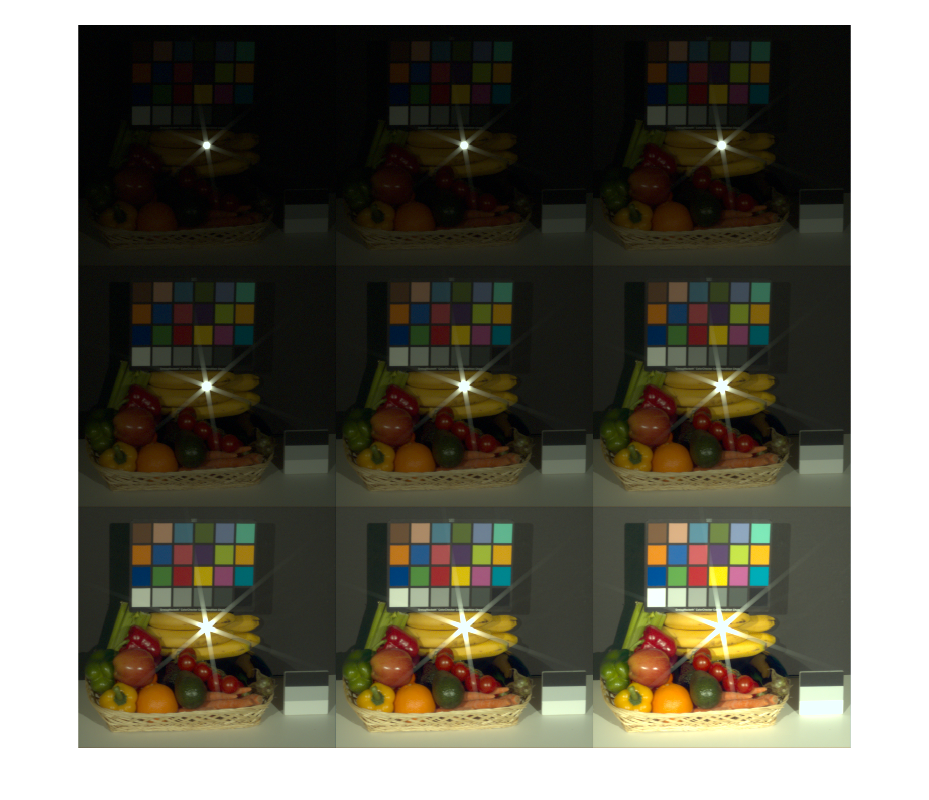

ieNewGraphWin; montage(imagecell);